t = 1:100;
signal = sin(t*pi/2)+sin(t*pi/3)+wgn(1,100,0)*0.3;

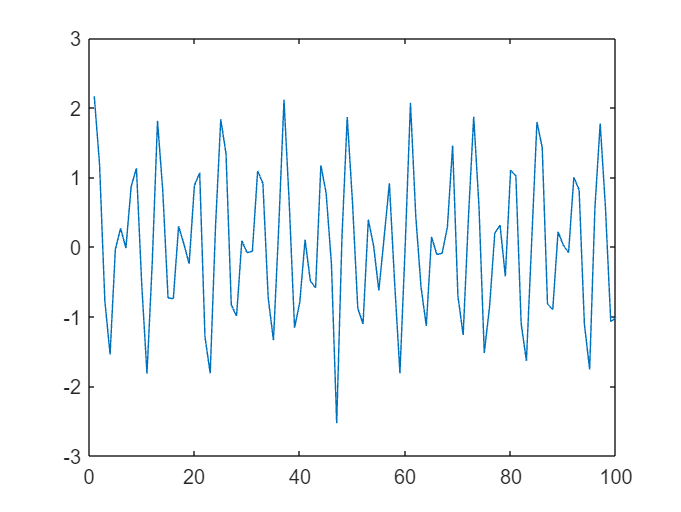

plot(t,signal);

% parameters:
alpha = 5000;       % bandwidth constraint
tau = 0.25;         % Lagrangian multipliers dual ascent time step
K = 5;              % number of modes
DC = 1;             % includes DC part (first mode at DC)

init = 1;           % initialize omegas randomly, may need multiple runs!

tol = K*10^-6;      % tolerance (for convergence)

[u, u_hat, omega]=VMD(signal, alpha, tau, K, DC, init, tol);

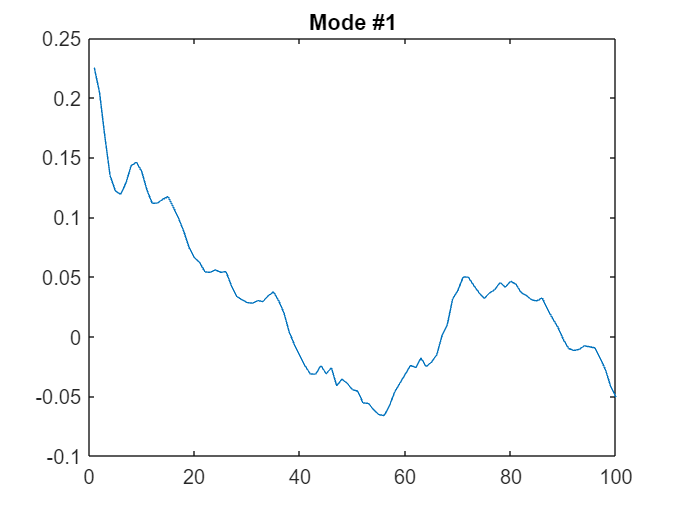

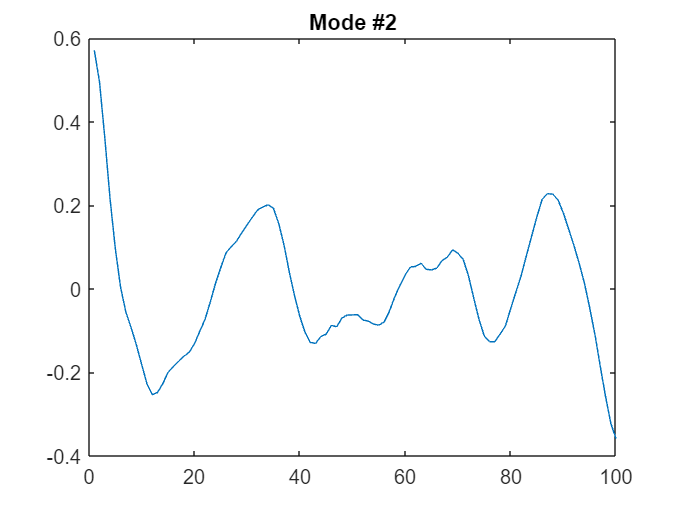

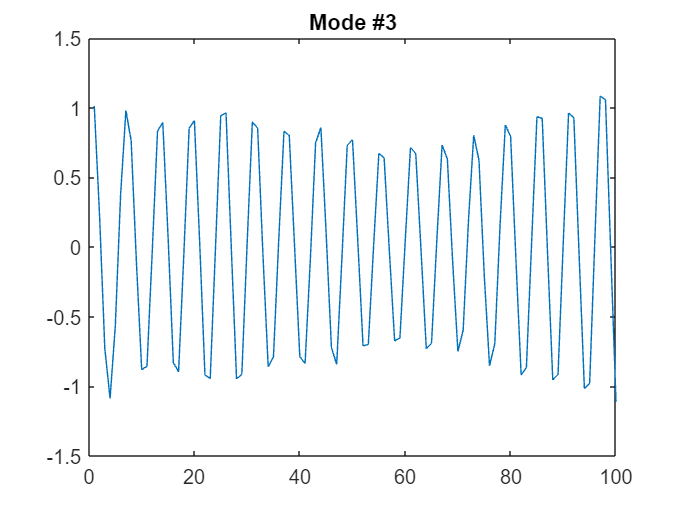

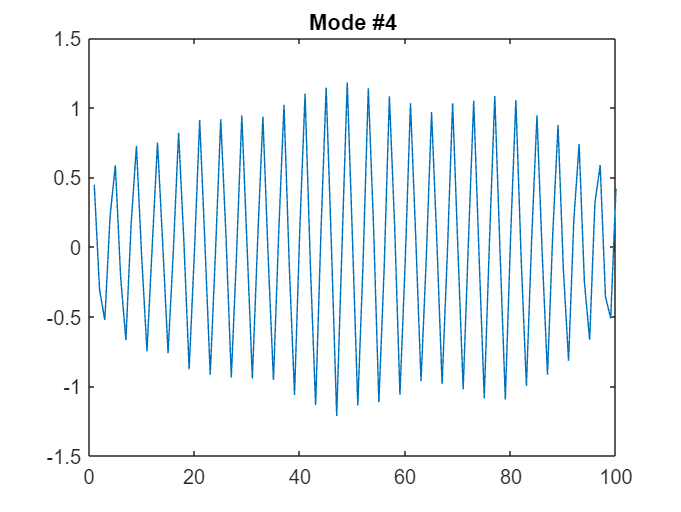

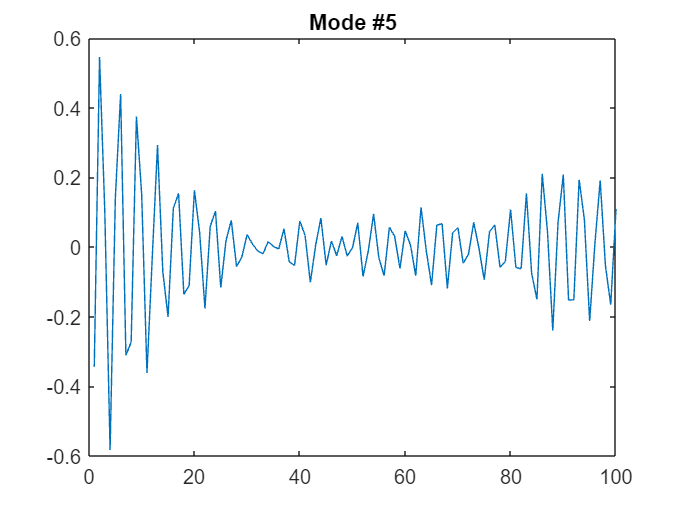

for k=1:K
    figure('Name', ['Mode #' num2str(k)]);
    plot(u(k,:));
    title(['Mode #' num2str(k)]);
end

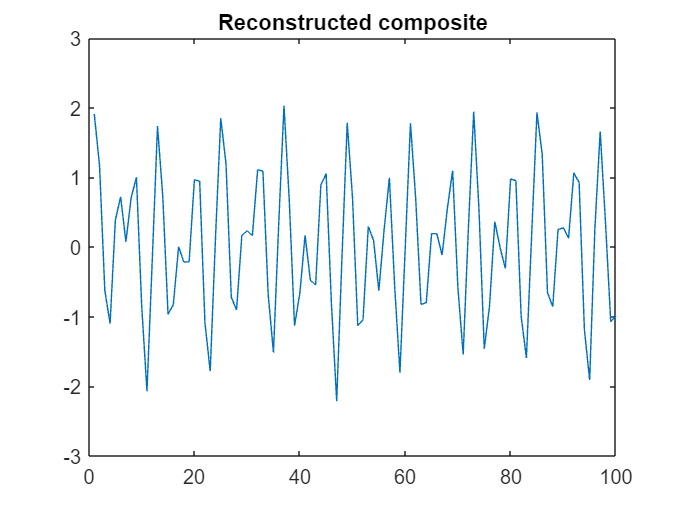

figure('Name', 'Reconstructed composite');
plot(sum(u));
title('Reconstructed composite');

Matlab function

[imf,residual,info] = vmd(signal,NumIMF=K);

info

info = struct with fields:
               ExitFlag: 0
     CentralFrequencies: [5×1 double]
          NumIterations: 500
    AbsoluteImprovement: 1.0199e-04
    RelativeImprovement: 1.9890e-05
     LagrangeMultiplier: [101×1 double]


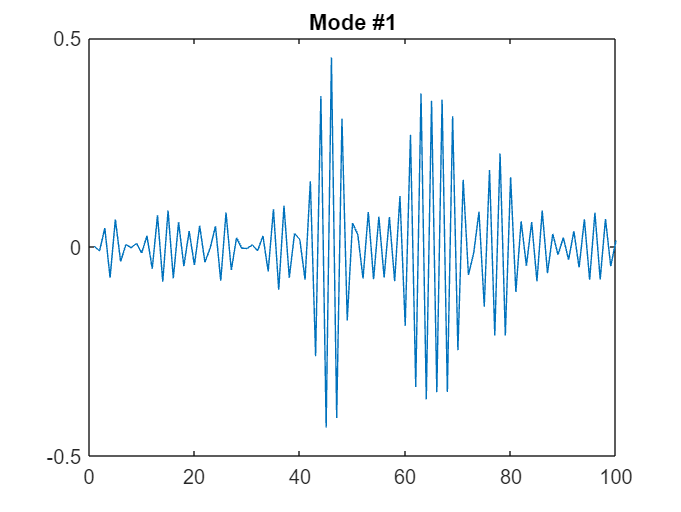

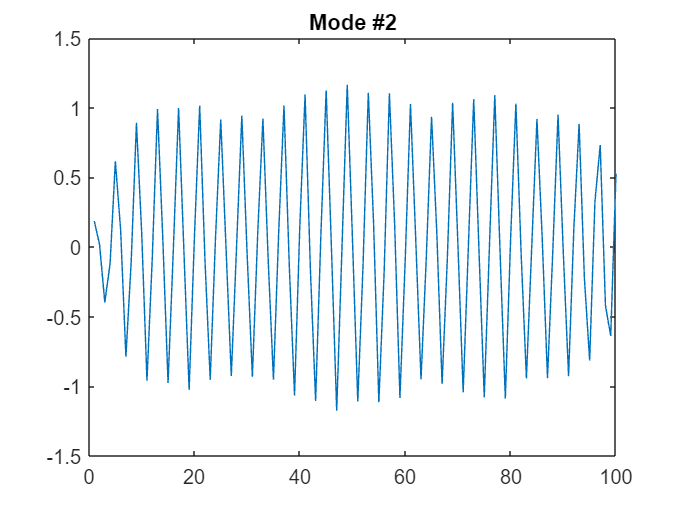

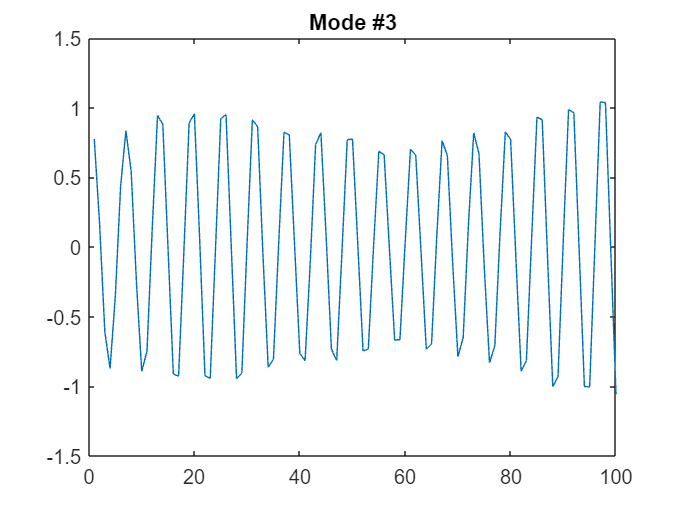

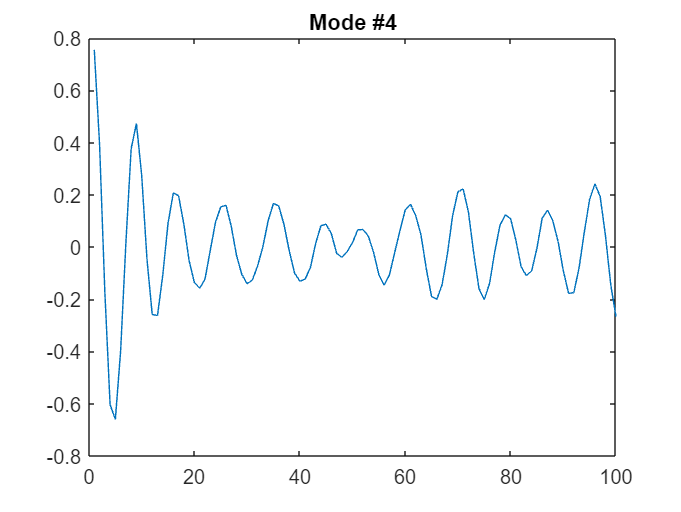

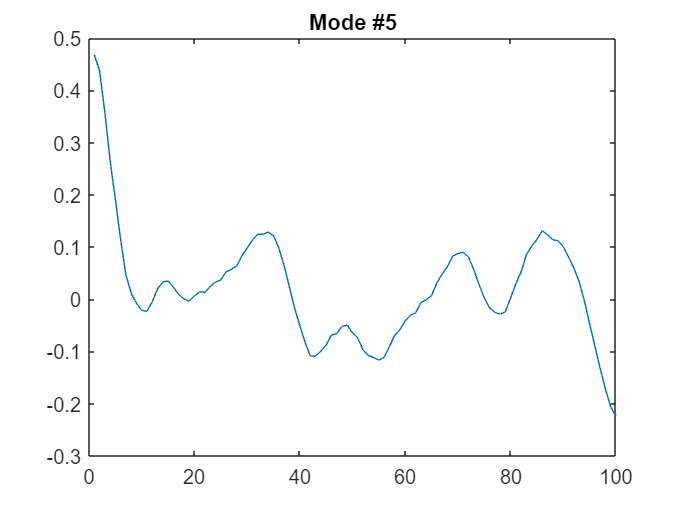

mlK = size(imf);
for k=1:mlK(2)
    figure('Name', ['Mode #' num2str(k)]);
    plot(imf(:,k));
    title(['Mode #' num2str(k)]);
end

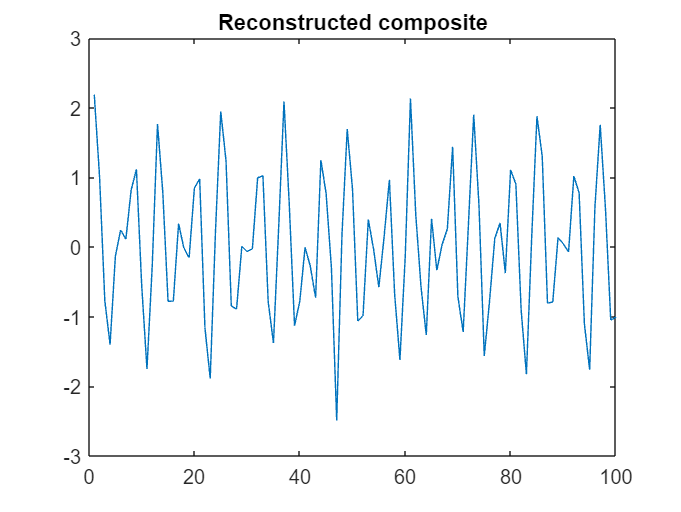

figure('Name', 'Reconstructed composite ml');
plot(sum(imf'));
title('Reconstructed composite');

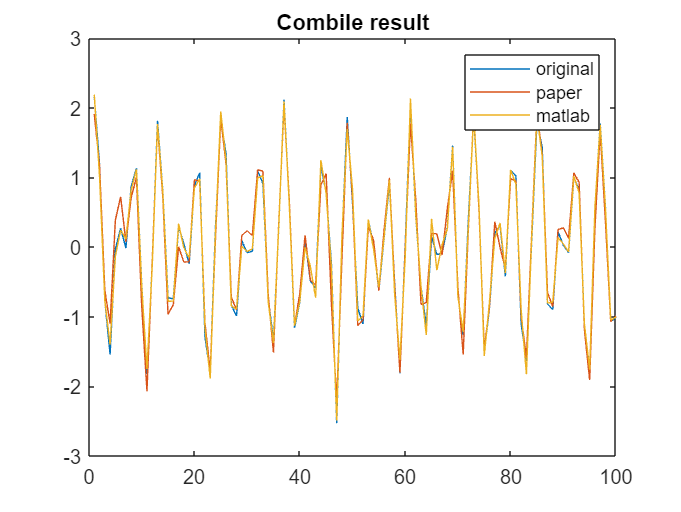

figure('Name', 'Combile');
plot(signal);
hold on
plot(sum(u));
hold on
plot(sum(imf'));
title('Combile result');
legend('original','paper','matlab');